rng('default');%initialize RNG for reproducibility

%test analysis of processivity etc
%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration
%processivity is synthesis limited
motorPar.kOff0 = 10*motorPar.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)

motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here

motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

[dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
t=dynamics.t;
x=dynamics.x;
nPlus=dynamics.nPlus;
nMinus=dynamics.nMinus;
Nplus=dynamics.Nplus;
Nminus=dynamics.Nminus;
vCargo=dynamics.vCargo;



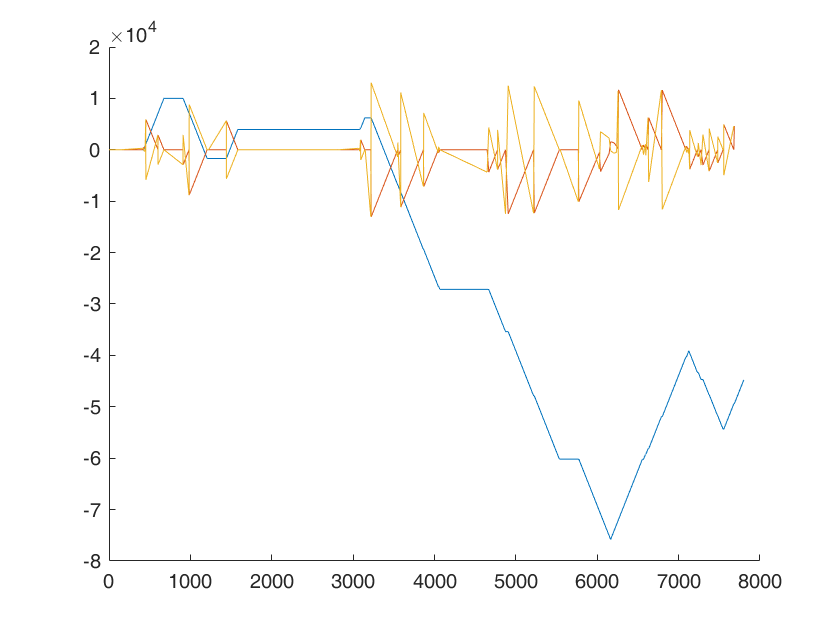

%find changes in dx,dt
dx=diff(x);
d2x=diff(dx);
ipt = findchangepts(x,'MaxNumChanges',numel(x));
tChgPt=t(ipt);
xChgPt=x(ipt);

figure;
hold all
plot(t,x);
plot(t(1:end-1),dx);
plot(t(1:end-2),d2x);

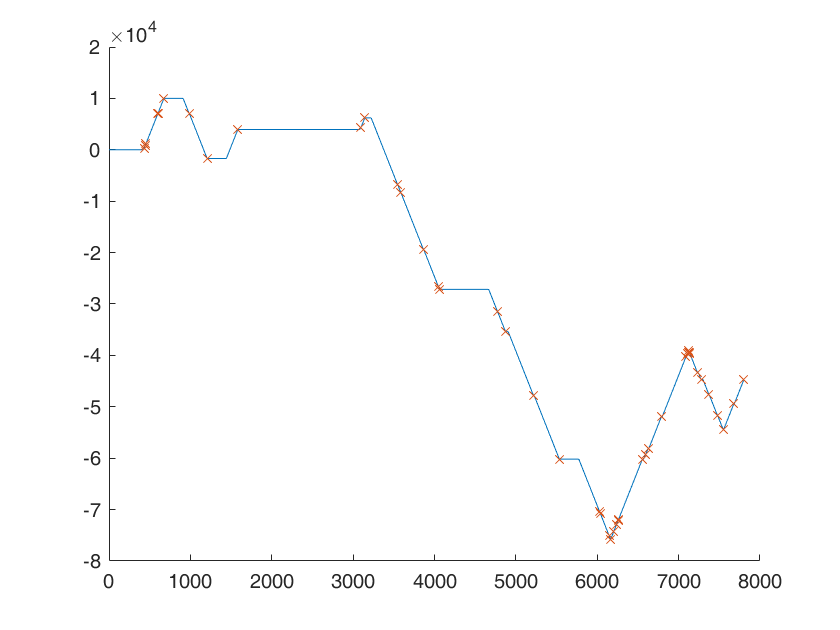

figure;
hold all
plot(t,x);
plot(tChgPt,xChgPt,'x')

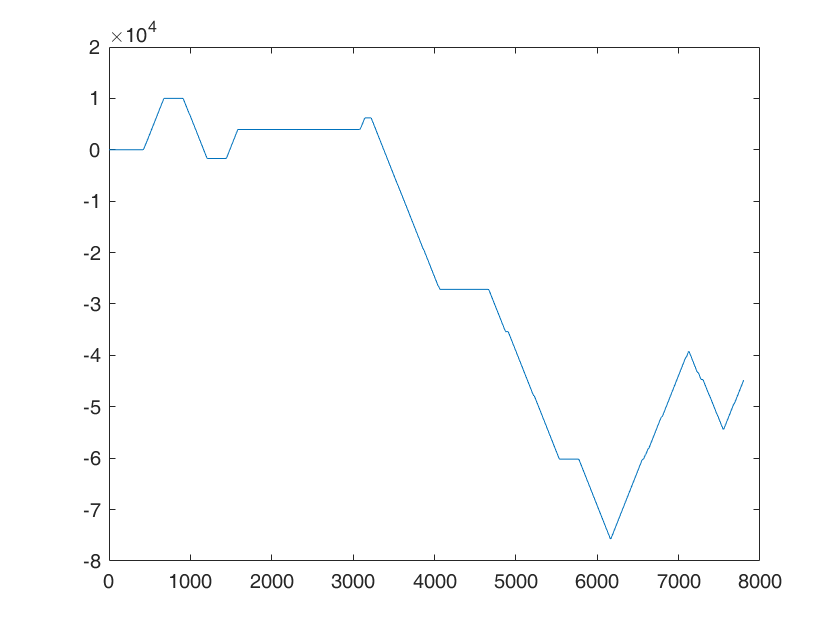


frameInterval= 6;%bin the data to the frame interval 
tFr = 0:frameInterval:max(t);
xFr = interp1(t,x,tFr);

figure;
plot(tFr,xFr);

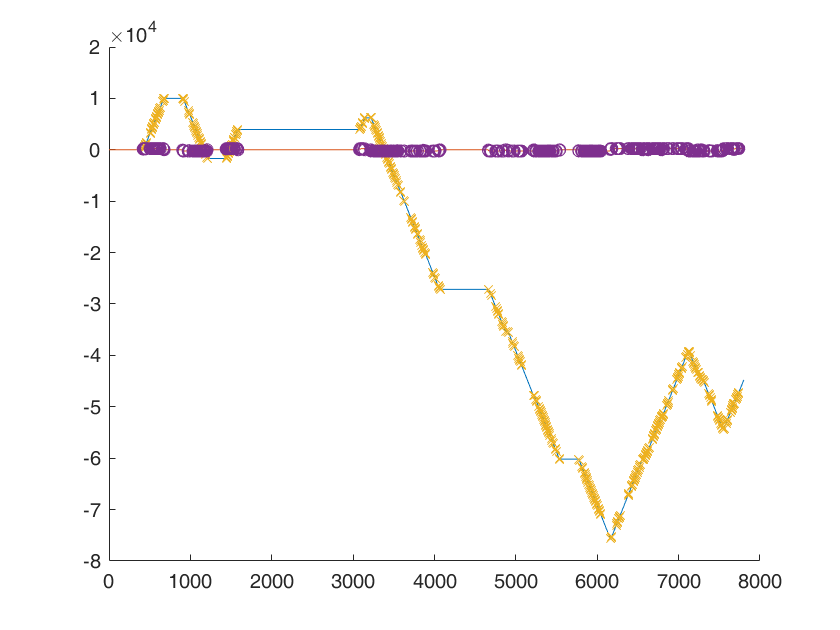

dxFr= diff(xFr);
ipt = findchangepts(dxFr,'MaxNumChanges',numel(dxFr));
tChgPt=tFr(ipt);
xChgPt=xFr(ipt);
dxChgPt=dxFr(ipt);
figure;
hold all
plot(t,x);
plot(tFr(1:end-1),dxFr);
plot(tChgPt,xChgPt,'x')
plot(tChgPt,dxChgPt,'o')

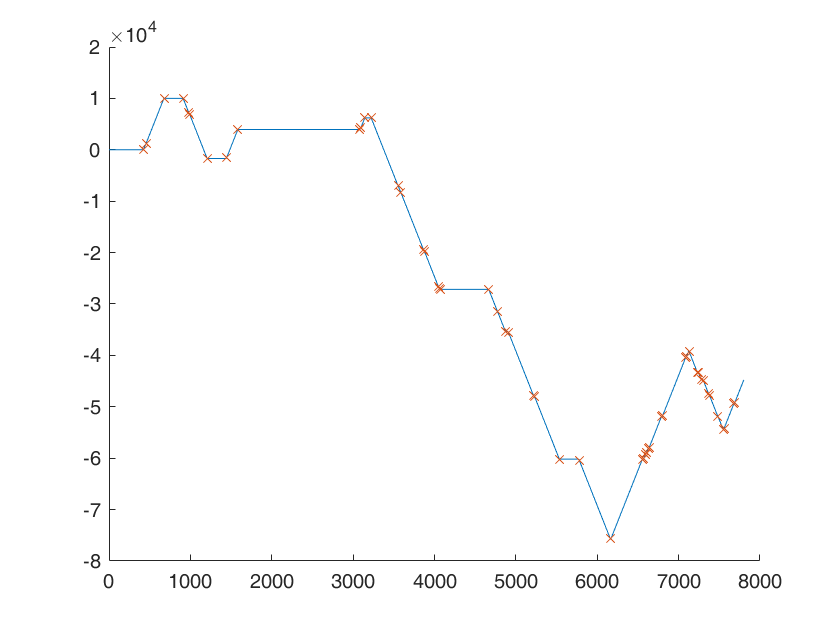


TF = ischange(xFr,'linear');
ipt=find(TF==1);
tChgPt=tFr(ipt);
xChgPt=xFr(ipt);

figure;
hold all
plot(t,x);
plot(tChgPt,xChgPt,'x')

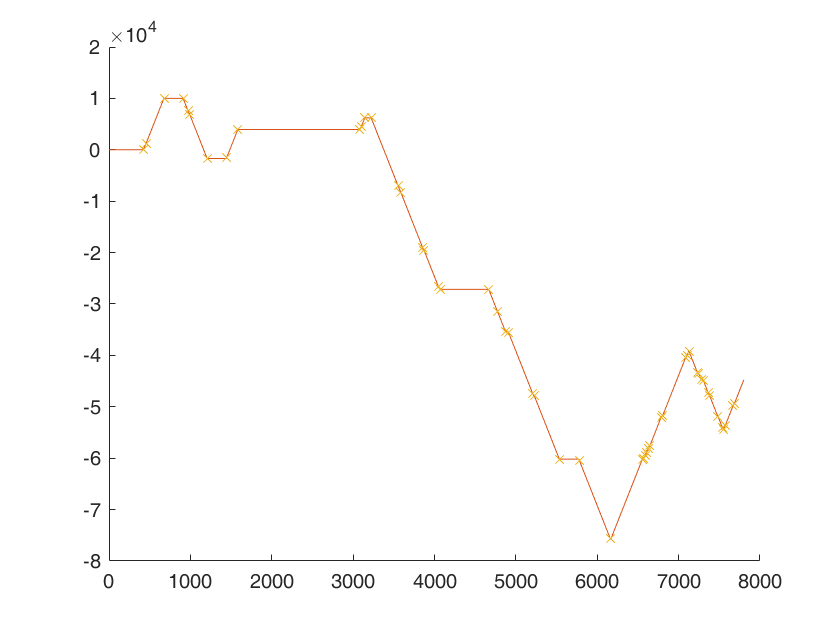

ipt = findchangepts(xFr,'Statistic','linear','MinThreshold',1,'MinDistance',3);
tChgPt=tFr(ipt);
xChgPt=xFr(ipt);
figure;
hold all
plot(t,x);
plot(tFr,xFr);
plot(tChgPt,xChgPt,'x')

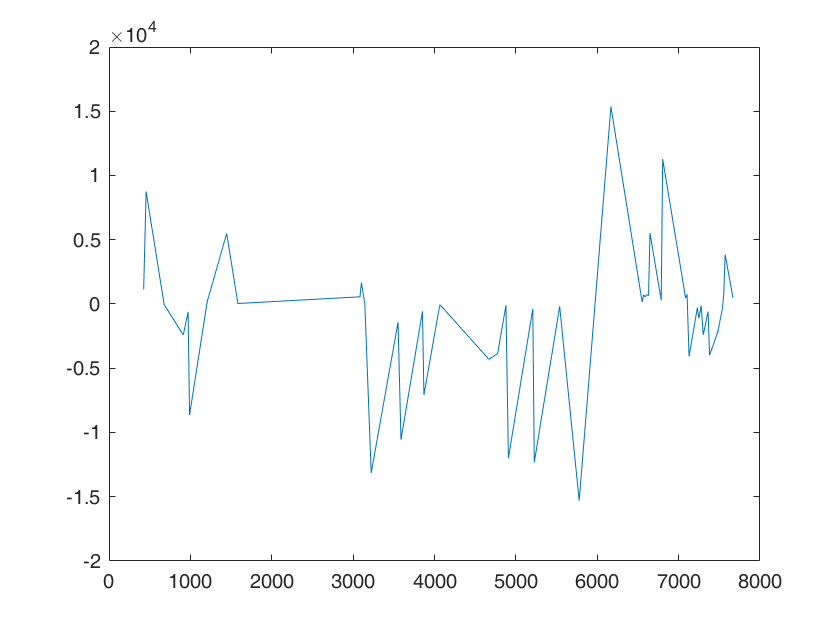


dx = diff(xChgPt);
dt = diff(tChgPt);
v=dx./dt;
figure;
plot(tChgPt(1:end-1),dx);

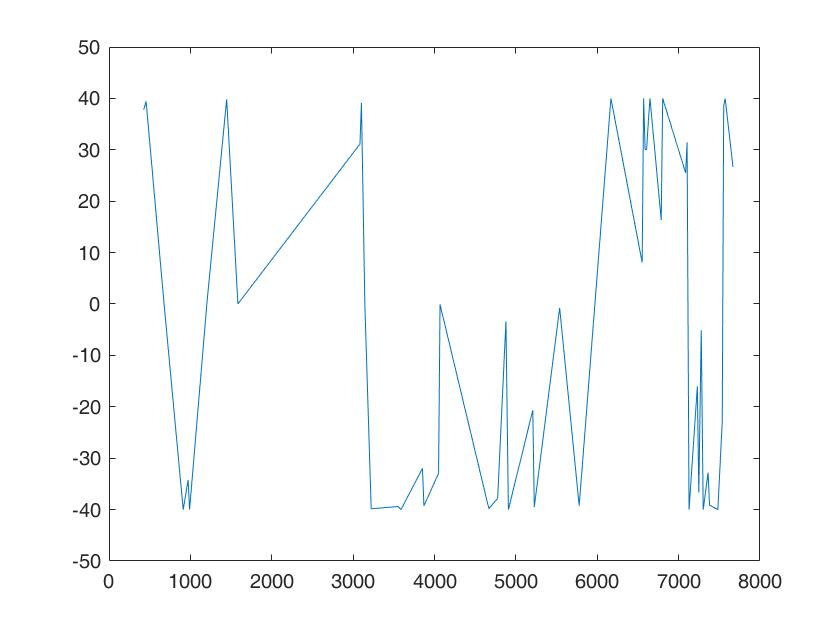


plot(tChgPt(1:end-1),v);

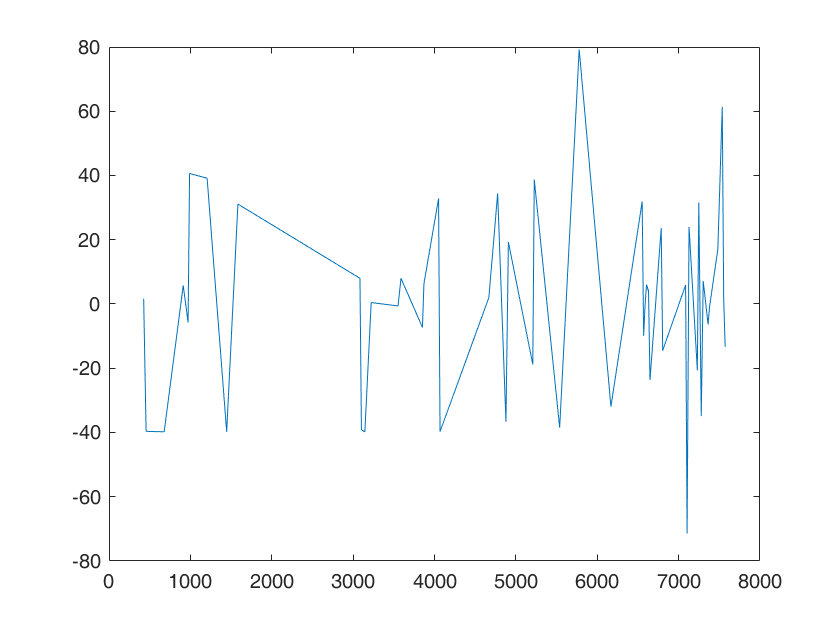

%ignore small speed changes 
% and only cound reversal or pausing
dv = diff(v);
plot(tChgPt(1:end-2),dv);

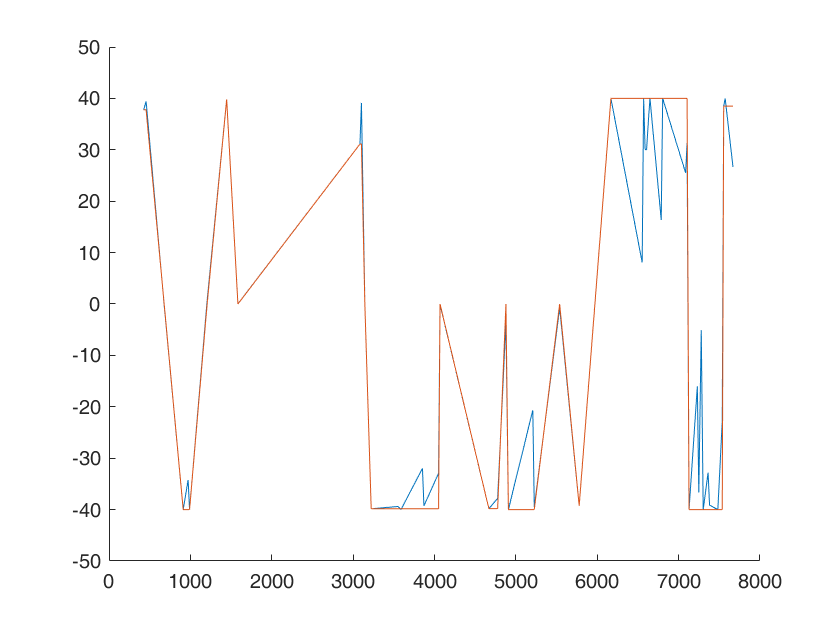

vThresh=5;
v2=v;
v2(abs(v2)<=vThresh)=0;
%filter out not reversal or pausing (small speed change)
for ii = 2:numel(v2)
    if sign(v2(ii-1))*sign(v2(ii))==1 & v2(ii)~=0
        v2(ii)=v2(ii-1);
    end
end
figure;
hold all;
plot(tChgPt(1:end-1),v);
plot(tChgPt(1:end-1),v2);

figure;
plot(tFr,xFr);

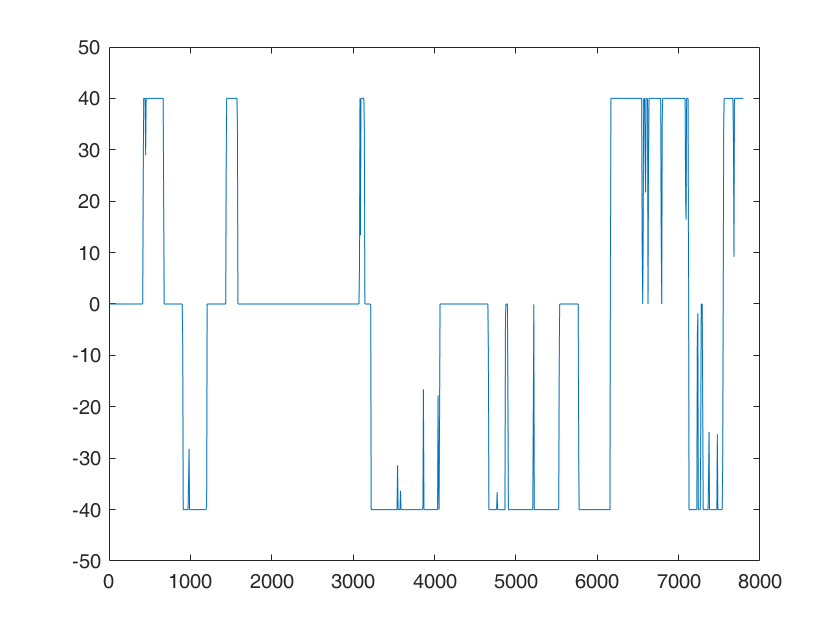

v=dxFr/frameInterval;
plot(tFr(1:end-1),v)

%filter out near zero speed
vThresh=5

vThresh = 5

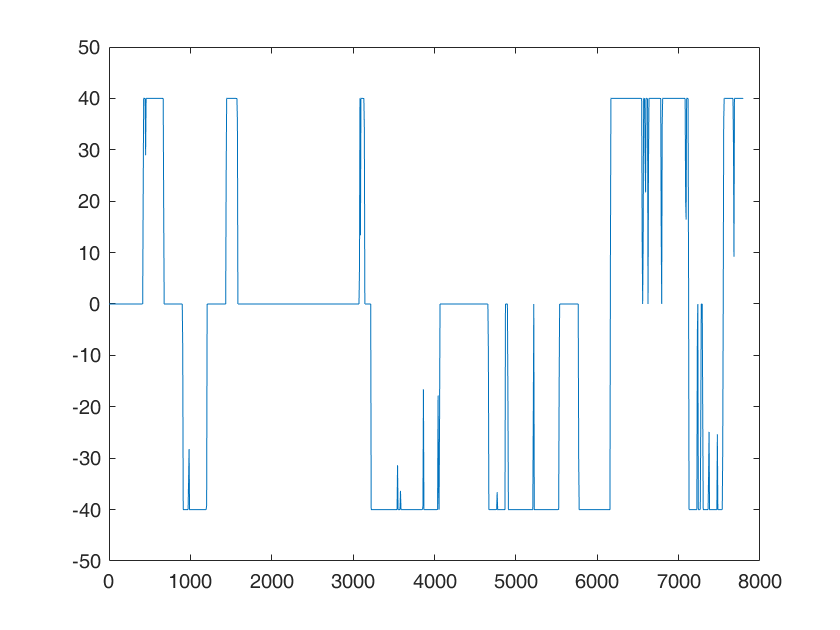

v2= v;
v2(abs(v2)<=vThresh)=0;
plot(tFr(1:end-1),v2)

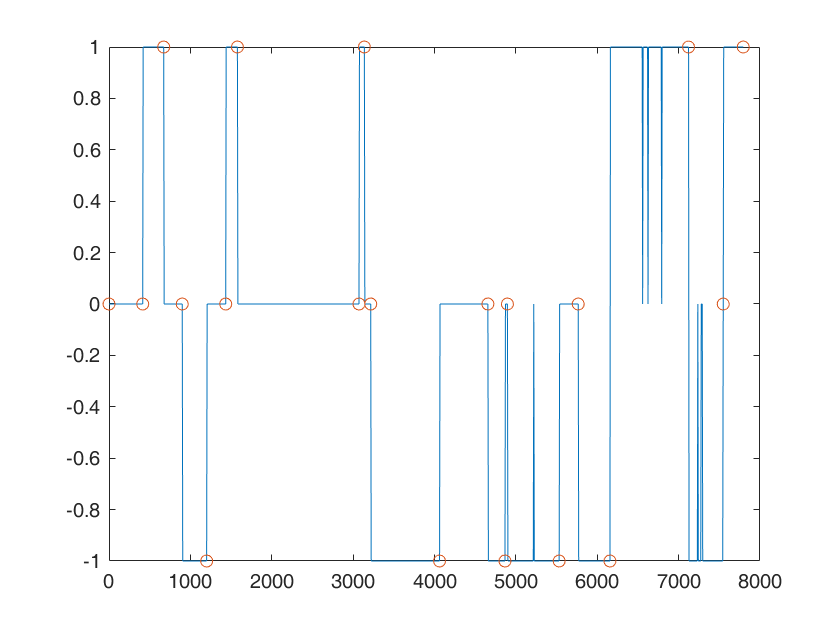

%todo:
%loop through and find sign changes or pauses
%need to identify states(beginning and end)
%measure type of state (motile, paused), length of state, average speed, and next state
%(motile paused)
%exclude states that are too close to last one
vSign = v2;
vSign(vSign>0) =1;
vSign(vSign<0) =-1;

plot(tFr(1:end-1),vSign);
chgpt=find(diff(vSign)~=0);
%add the first and last frames as states
chgpt=[1,chgpt,numel(tFr)-1];
hold all;
tChgPt=tFr(chgpt);
%plot(tChgPt,vSign(chgpt),'x')
%Filter out short trajectories
frameThresh=4;
chgptFilt=chgpt;
ii = 2;
while ii <= numel(chgptFilt)
    if (chgptFilt(ii)-chgptFilt(ii-1))<frameThresh
        if vSign(chgptFilt(ii-1))==vSign(chgptFilt(ii)+1)%previous state same as current state
            %delete both chgptFilt
            chgptFilt(ii-1:ii)=[];
            ii=ii-1;
        else
            %dlete only previous chgptFilt
            chgptFilt(ii-1)=[];
        end
    else
        ii=ii+1;
    end
end
tChgPtFilt=tFr(chgptFilt);
plot(tChgPtFilt,vSign(chgptFilt),'o')

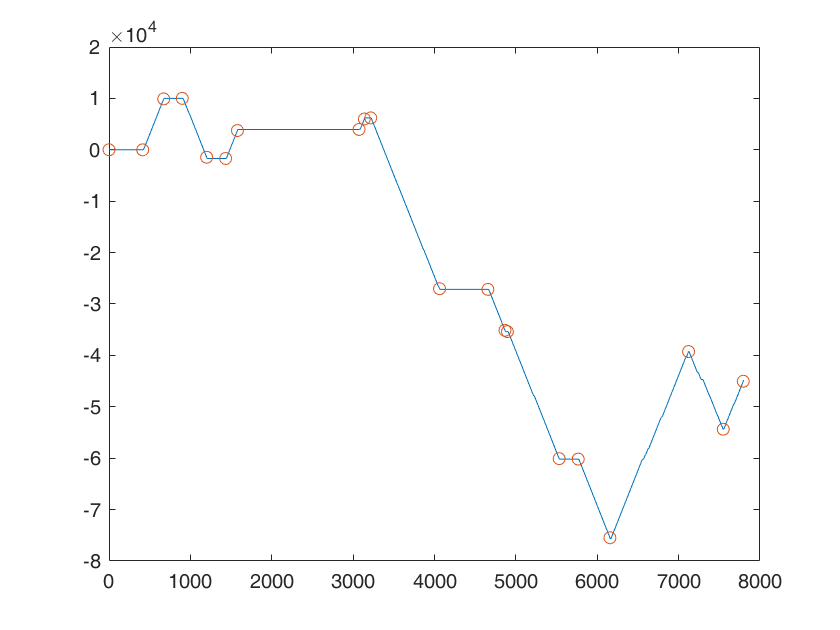

figure;
plot(tFr,xFr);
hold all;
plot(tFr(chgptFilt),xFr(chgptFilt),'o');

simResult = table;
nState = numel(chgptFilt)-2;%have to discard the last state as dont know what it transitioned to
runID = 1;
simResult.runID = ones(nState,1)*runID;
%loop through and measure state properties
for ii=1:nState
    startIdx = chgptFilt(ii);
    endIdx  = chgptFilt(ii+1);
    nextStateIdx=chgptFilt(ii+2);
    simResult.duration(ii)= tFr(endIdx)-tFr(startIdx);
    simResult.processivity(ii)=abs(xFr(endIdx)-xFr(startIdx));
    simResult.speed(ii)=simResult.processivity(ii)/simResult.duration(ii);
    simResult.isMotile(ii)=vSign(endIdx)~=0;
    simResult.isNextStateMotile(ii)=vSign(nextStateIdx)~=0;    
end
simResult

simResult = 18×6 table
    runID    duration    processivity     speed     isMotile    isNextStateMotile
    _____    ________    ____________    _______    ________    _________________

      1         414              0             0     false            true       
      1         258         9900.3        38.373     true             false      
      1         228         112.76       0.49457     false            true       
      1         300          11466        38.219     true             false      
      1         234         235.46        1.0062     false            true       
      1         144           5436         37.75     true             false      
      1        1494         213.18       0.14269     false            true       
      1          66         2039.6

%OK looks like the automatic analysis works ok now
%Next, implement as a function, then run some sims as a function of
%concentration
zeroSpeedThresh = vThresh;
switchTooCloseThresh = frameThresh;

[simResultAuto, chgptAuto, tFrAuto,xFrAuto] = analyseSimDynamics(t,x,frameInterval,zeroSpeedThresh, switchTooCloseThresh);

simResultAuto

simResultAuto = 18×6 table
    runID    duration    processivity     speed     isMotile    isNextStateMotile
    _____    ________    ____________    _______    ________    _________________

      1         414              0             0     false            true       
      1         258         9900.3        38.373     true             false      
      1         228         112.76       0.49457     false            true       
      1         300          11466        38.219     true             false      
      1         234         235.46        1.0062     false            true       
      1         144           5436         37.75     true             false      
      1        1494         213.18       0.14269     false            true       
      1          66         20

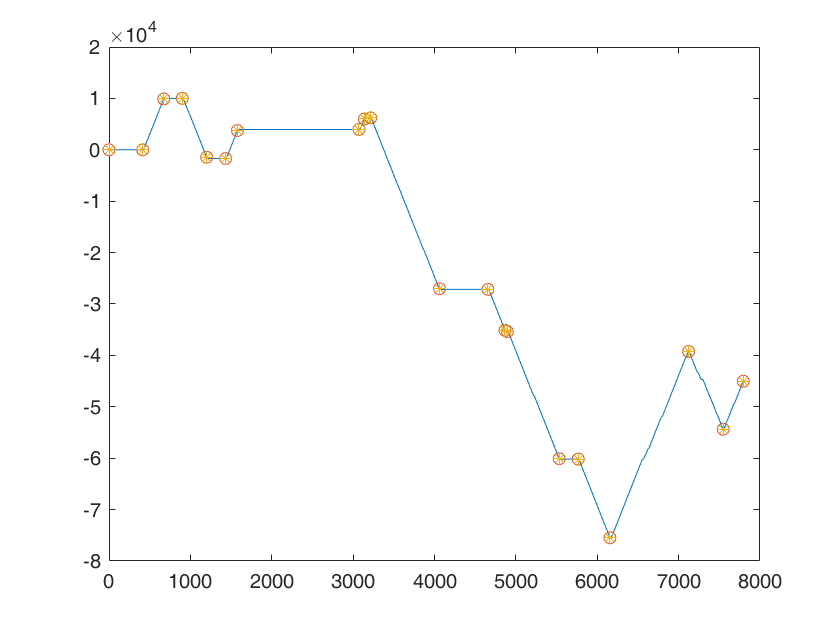

figure;
plot(tFr,xFr);
hold all;
plot(tFr(chgptFilt),xFr(chgptFilt),'o');
plot(tFr(chgptAuto),xFr(chgptAuto),'*');

try a short loop to get enough data for estimate of rates processivities, lifetime

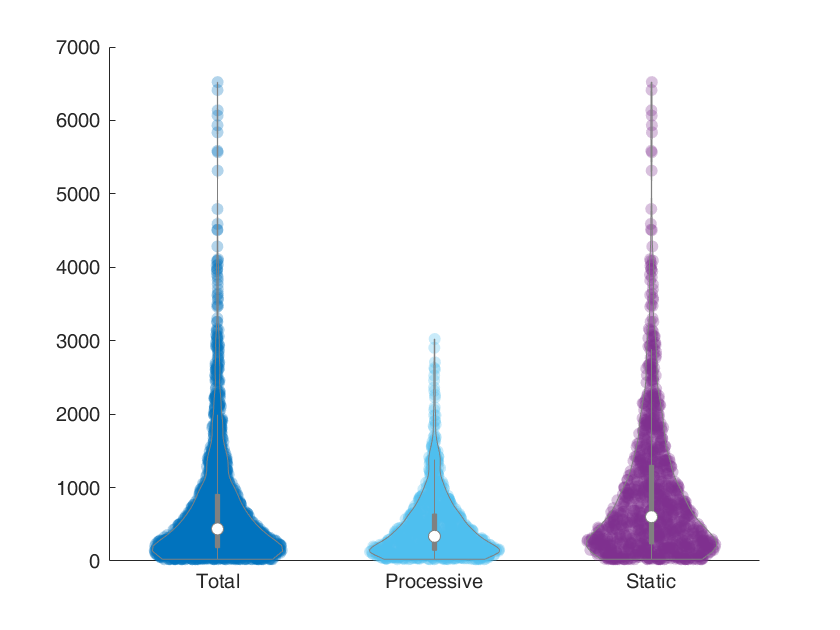

rng('default');%initialize RNG for reproducibility

%test analysis of processivity etc
%choose params which support stable tug of war, ie
% high native processivity, low PG unbinding rate eps0<< koff0
% frequent PG binding, pi0>> kOn0
motorPar.kOn0 = 0.5/60; %rate of single motor (synthase) binding to cargo (mreB) (From Stu data)
motorPar.pi0 =10*motorPar.kOn0; %single motor binding rate s^-1 %promotes tug of war
motorPar.eps0=0.3/60;%single motor unbinding rate s^-1 %promotes tug of war, also at low concentration
%processivity is synthesis limited
motorPar.kOff0 = 10*motorPar.eps0; %rate of single motor (synthase) unbinding from cargo (mreB)

motorPar.Fdetach = 1;%detachment force pN nm
motorPar.Fstall = 100; %stall force pN nM
motorPar.vF=40;%forward velocity nm/s
motorPar.vB=0.1;%backward velocity nm/s
motorPar.Nmax = 1;
motorPar.motorConcentration =0.1;%arb units, essentiall scaling of low synthase concentration data here

motorState=motorPar;
motorState.Nplus=0;%initial total number of plus motors 
motorState.Nminus=0;%initial total number of bound plus motors 
motorState.nPlus=0;%number of bound plus motors 
motorState.nMinus=0;%number of bound minus motors

simPar.nStep= 100;

frameInterval=6;
zeroSpeedThresh=5;
switchTooCloseThresh=4;

nSimRepeat = 100;
simResult=table;
for ii=1:nSimRepeat
    [dynamics] = lipowskiWithUnbindingSim(motorState,simPar);
    t=dynamics.t;
    x=dynamics.x;
    runID=ii;
    [simResultCur] = analyseSimDynamics(t,x,frameInterval,zeroSpeedThresh, switchTooCloseThresh, runID);
    simResult=[simResult;simResultCur];
end

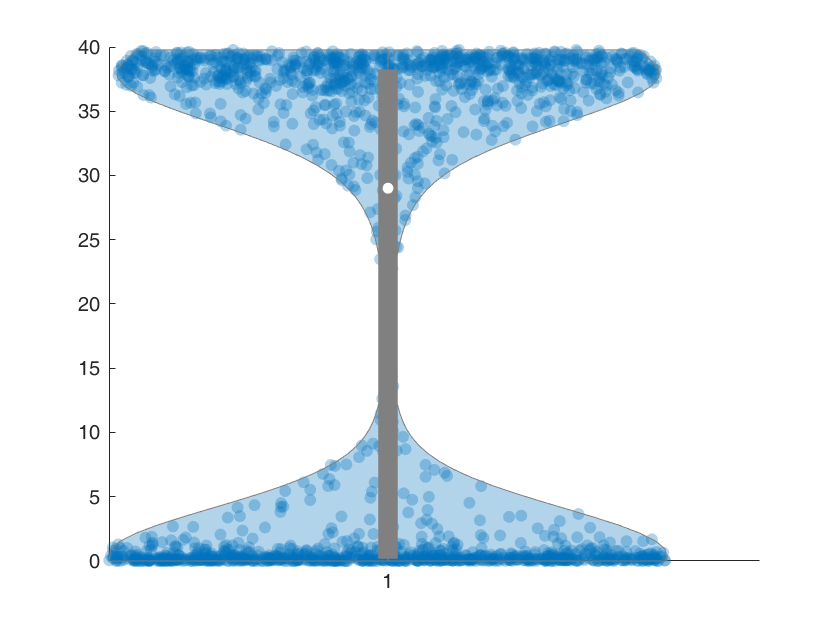

figure;
violinplot(simResult.speed);

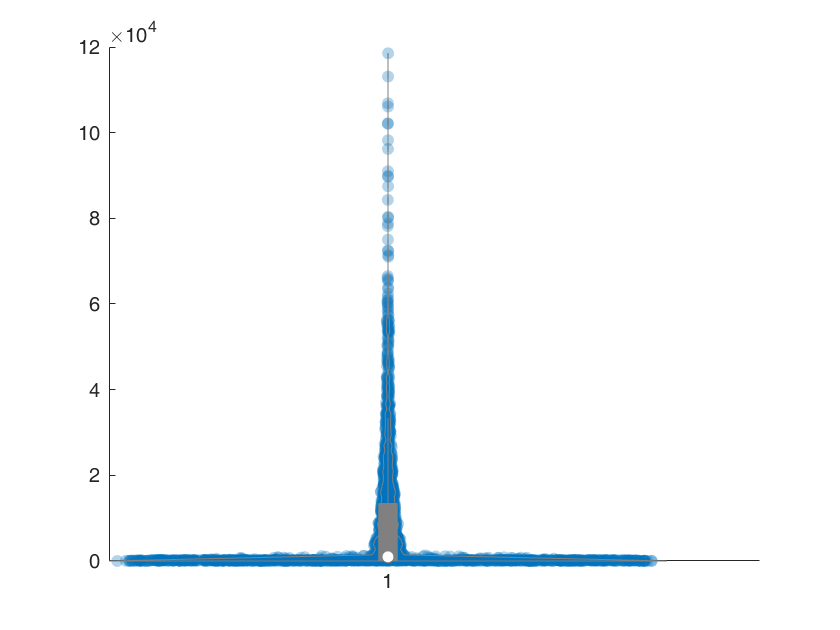

figure;
violinplot(simResult.processivity);

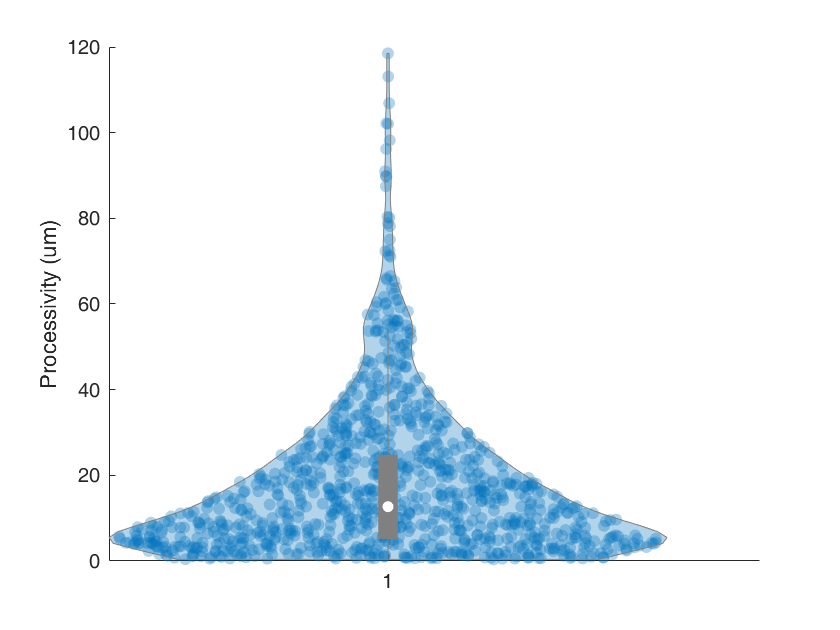

figure;
violinplot(simResult.processivity(simResult.isMotile==1)/1000);  
ylabel('Processivity (um)');

simResult_motile= simResult(simResult.isMotile==1,:);
simResult_static= simResult(simResult.isMotile==0,:);
%processive_rates

processiveEndsInPause = simResult_motile(simResult_motile.isNextStateMotile==0,:);
processiveEndsInReversal = simResult_motile(simResult_motile.isNextStateMotile==1,:);
pause_processive_rate= size(processiveEndsInPause,1)/sum(simResult_motile.duration)

pause_processive_rate = 0.0019

reversal_processive_rate = size(processiveEndsInReversal,1)/sum(simResult_motile.duration)

reversal_processive_rate = 2.2247e-04

staticToMotile_rate = size(simResult_static,1)/sum(simResult_static.duration)

staticToMotile_rate = 0.0011


fractionMotile = sum(simResult_motile.duration)/sum(simResult.duration)

fractionMotile = 0.3359

%implement rate calculations as functions so can do bootstrap CIs
pause_processive_rateFcn= @(simResult) sum(simResult.isMotile==1 & simResult.isNextStateMotile==0)/ sum(simResult.duration(simResult.isMotile==1));
pause_processive_rate=pause_processive_rateFcn(simResult)

pause_processive_rate = 0.0019

pause_processive_rate_ci = bootci(1000,pause_processive_rateFcn,simResult)

pause_processive_rate_ci =     0.0018
    0.0020


reversal_processive_rateFcn= @(simResult) sum(simResult.isMotile==1 & simResult.isNextStateMotile==1)/ sum(simResult.duration(simResult.isMotile==1));
reversal_processive_rate=reversal_processive_rateFcn(simResult)

reversal_processive_rate = 2.2247e-04

reversal_processive_rate_ci=bootci(1000,reversal_processive_rateFcn,simResult)

reversal_processive_rate_ci = 	1.0e+-3 *

    0.1851
    0.2688



staticToMotile_rateFcn = @(simResult) sum(simResult.isMotile==0)/sum(simResult_static.duration);
staticToMotile_rate = staticToMotile_rateFcn(simResult)

staticToMotile_rate = 0.0011

staticToMotile_rate_ci=bootci(1000,staticToMotile_rateFcn,simResult)

staticToMotile_rate_ci =     0.0010
    0.0011



fractionMotileFcn = @(simResult) sum(simResult.duration(simResult.isMotile==1))/sum(simResult.duration);
fractionMotile = fractionMotileFcn(simResult)

fractionMotile = 0.3359

fractionMotile_ci=bootci(1000,fractionMotileFcn,simResult)

fractionMotile_ci =     0.3100
    0.3667


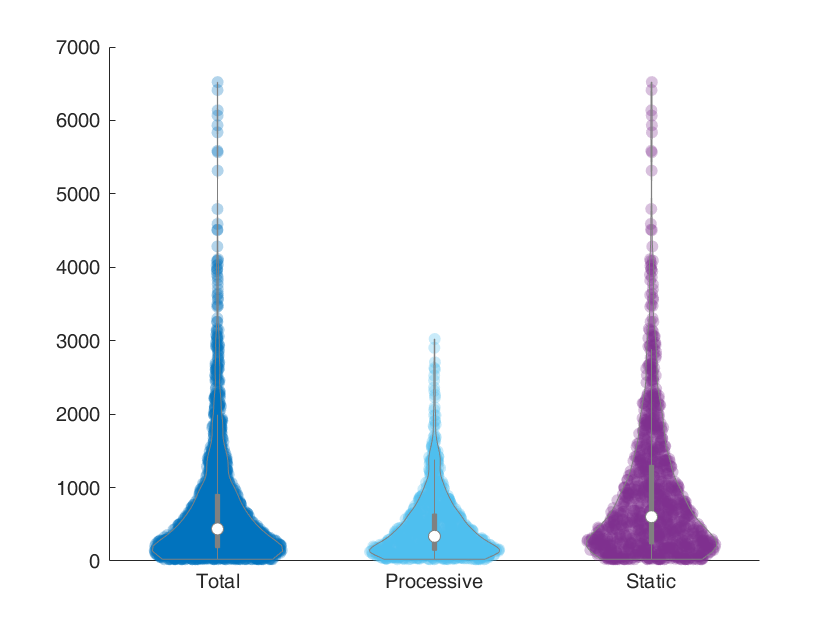


lifetime.Total = simResult.duration;
lifetime.Processive = simResult.duration(simResult.isMotile==1);
lifetime.Static = simResult.duration(simResult.isMotile==0);
figure;
violinplot(lifetime);


% instant_rate = 1./ processiveEndsInReversal.duration;
% mean(instant_rate)
% median(instant_rate)
% figure;
% violinplot(instant_rate);